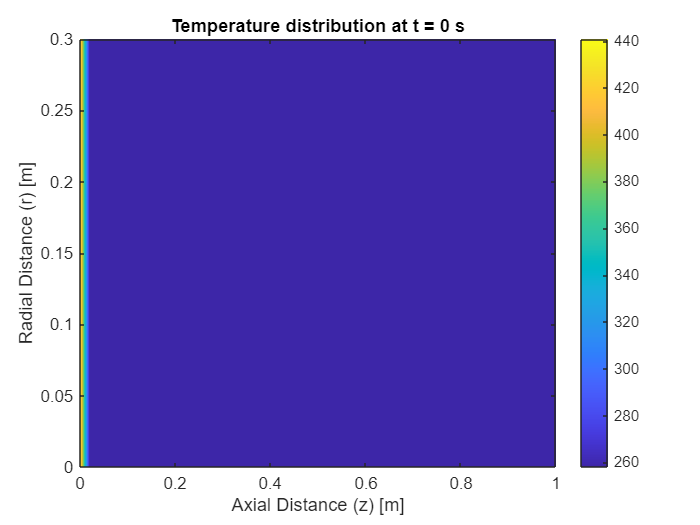

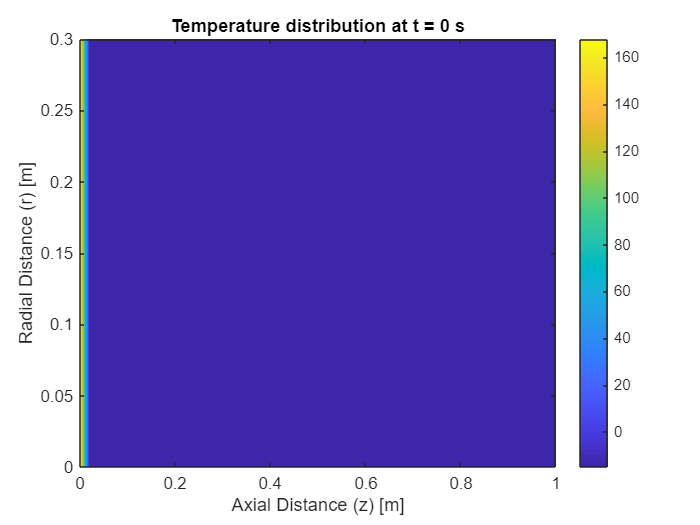

% Heat conduction of a solid medium (Copper Material): Transient and steady-state analysis with visualization.
% Student number: 002410999

% Constants taken into considerations
R = 0.3; % Radius of the cylinder (m)
H = 1; % Height of the cylinder (m)
nr = 50; % Number of radial nodes assumed
nz = 50; % Number of axial nodes assumed
dr = R / (nr - 1); % Radial step size
dz = H / (nz - 1); % Axial step size
K = 385; % Thermal conductivity of copper (W/m·K)
rho = 8850; % Density of copper (kg/m^3)
cp = 392; % Specific heat capacity of copper (J/kg·K)
alpha = K / (rho * cp); % Thermal diffusivity calculation formula(m^2/s)

% Boundary and Initial Conditions
T1 = 450; % Given Heated circular end temperature (K)
T0 = 258; % Given Ambient temperature (K)

% Initial temperature distribution (ambient temperature everywhere)
T = T0 * ones(nr, nz);

% Setting boundary condition at the heated end (z = 0)
T(:, 1) = T1;

% Reshaping the temperature matrix for ODE solver
T_vect = reshape(T, [], 1);

% Time simulation parameters
t_end = 50; % Maximum simulation time (seconds)
opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);

% Solving the heat equation using ODE45 solver
[t_sol, T_sol] = ode45(@(t, T) heat_eqn(t, T, nr, nz, dr, dz, alpha, T1, T0), [0 t_end], T_vect, opts);

% Visualization: Time evolution
r = linspace(0, R, nr);
z = linspace(0, H, nz);
[R_grid, Z_grid] = meshgrid(r, z);

figure;
for i = 1:length(t_sol)
    T_current = reshape(T_sol(i, :), nr, nz);
    contourf(Z_grid, R_grid, T_current', 20, 'LineColor', 'none');
    colorbar;
    xlabel('Axial Distance (z) [m]');
    ylabel('Radial Distance (r) [m]');
    title(['Temperature distribution at t = ', num2str(t_sol(i)), ' s']);
    pause(0.2);
end

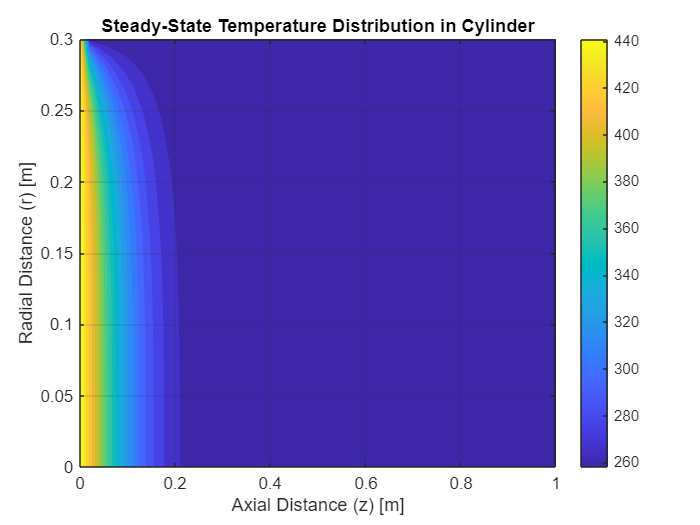


% Steady-state visualization
T_steady = reshape(T_sol(end, :), nr, nz);

% 2D Contour plot
figure;
contourf(Z_grid, R_grid, T_steady', 20, 'LineColor', 'none');
colorbar;
xlabel('Axial Distance (z) [m]');
ylabel('Radial Distance (r) [m]');
title('Steady-State Temperature Distribution in Cylinder');
grid on;

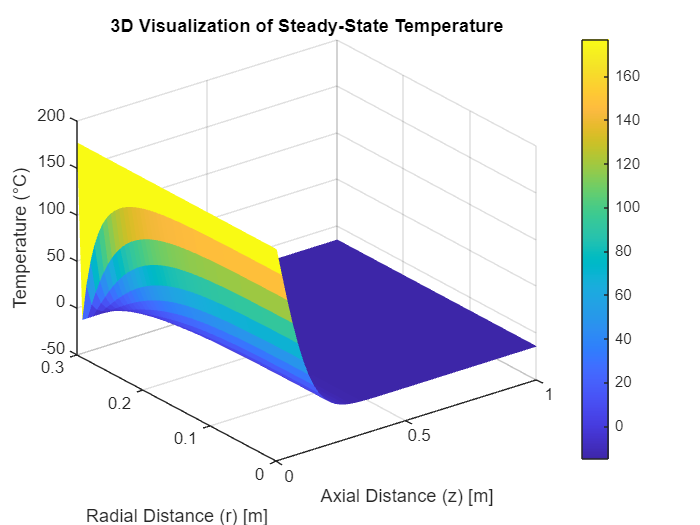


% 3D Surface plotting
figure;
surf(Z_grid, R_grid, T_steady', 'EdgeColor', 'none');
colorbar;
xlabel('Axial Distance (z) [m]');
ylabel('Radial Distance (r) [m]');
zlabel('Temperature (°C)');
title('3D Visualization of Steady-State Temperature');
view(3);

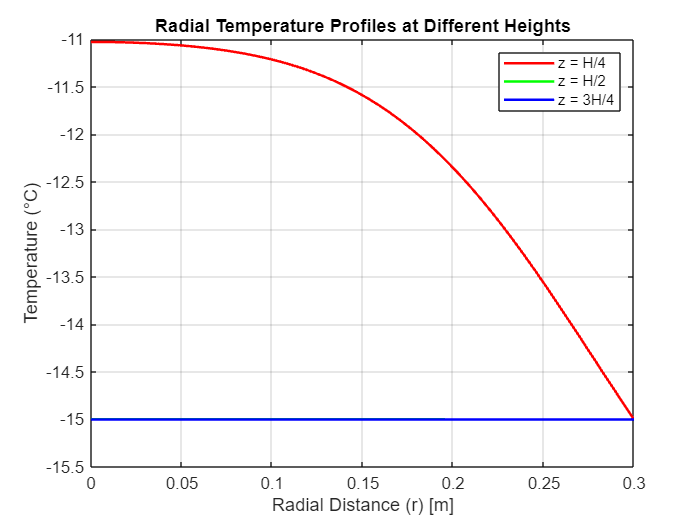


% Radial temperature profiles
figure;
plot(r, T_steady(:, round(nz/4)), 'r', 'LineWidth', 1.5); hold on;
plot(r, T_steady(:, round(nz/2)), 'g', 'LineWidth', 1.5);
plot(r, T_steady(:, round(3*nz/4)), 'b', 'LineWidth', 1.5);
legend('z = H/4', 'z = H/2', 'z = 3H/4');
xlabel('Radial Distance (r) [m]');
ylabel('Temperature (°C)');
title('Radial Temperature Profiles at Different Heights');
grid on;

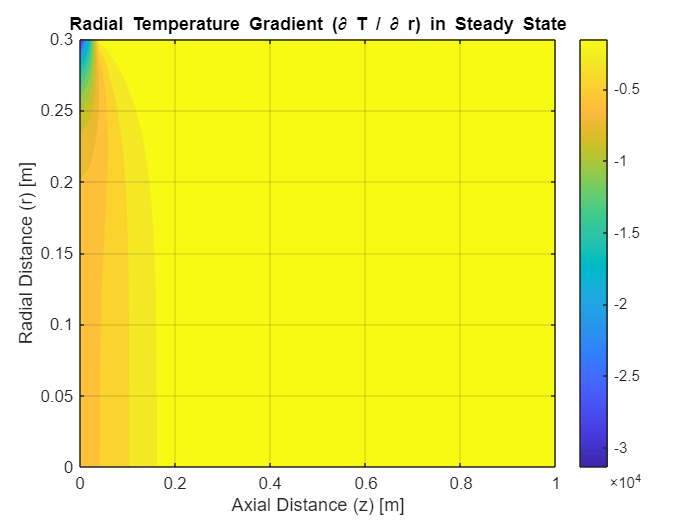


% Calculate gradients
[dr_T, dz_T] = gradient(T_steady, dr, dz);

% Visualization of radial temperature gradient
figure;
contourf(Z_grid, R_grid, dr_T', 20, 'LineColor', 'none');
colorbar;
xlabel('Axial Distance (z) [m]');
ylabel('Radial Distance (r) [m]');
title('Radial Temperature Gradient (\partial T / \partial r) in Steady State');
grid on;

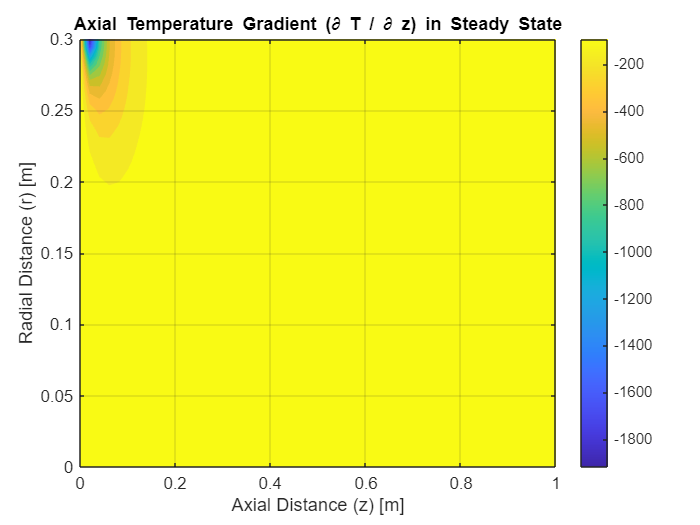


% Visualization of axial temperature gradient
figure;
contourf(Z_grid, R_grid, dz_T', 20, 'LineColor', 'none');
colorbar;
xlabel('Axial Distance (z) [m]');
ylabel('Radial Distance (r) [m]');
title('Axial Temperature Gradient (\partial T / \partial z) in Steady State');
grid on;


% Heat equation function
function dTdt = heat_eqn(~, T_vec, nr, nz, dr, dz, alpha, T1, T0)
    T = reshape(T_vec, nr, nz);
    dT = zeros(size(T));

    % Interior points: radial and axial conduction
    for i = 2:nr-1
        for j = 2:nz-1
            radial_term = (T(i+1, j) - 2*T(i, j) + T(i-1, j)) / dr^2 + ...
                          (1 / (i * dr)) * (T(i+1, j) - T(i-1, j)) / (2 * dr);
            axial_term = (T(i, j+1) - 2*T(i, j) + T(i, j-1)) / dz^2;
            dT(i, j) = alpha * (radial_term + axial_term);
        end
    end

    % Boundary conditions evaluations
    dT(:, 1) = 0; % Fixed temperature at z = 0 (heated end)
    dT(:, nz) = 0; % Fixed temperature at z = H (ambient)
    dT(1, :) = dT(2, :); % Symmetry at r = 0
    dT(nr, :) = 0; % Insulated boundary at r = R

    % Reshape derivative matrix back to vector form
    dTdt = reshape(dT, [], 1);
end

